**PROCESADO DE DATOS**

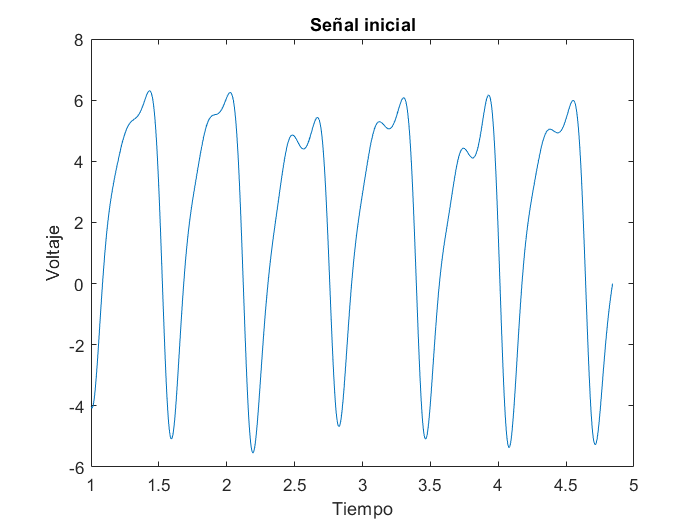

% Ruta del archivo
ruta_pa = 'D:\Master\Segundo Cuatrimestre\Trabajo Fin de Master\TFM presion arterial\Excel\PWL_buena1\Macros\Pwl_macro.csv';

% Se lee el csv
datos_pa = csvread(ruta_pa);

% Extraemos columnas
base_tiempos = datos_pa(:, 1);
voltaje_inicial = datos_pa(:, 2);

% Representamos los datos guardados
plot(base_tiempos, voltaje_inicial);
xlabel('Tiempo');
ylabel('Voltaje');
title('Señal inicial');

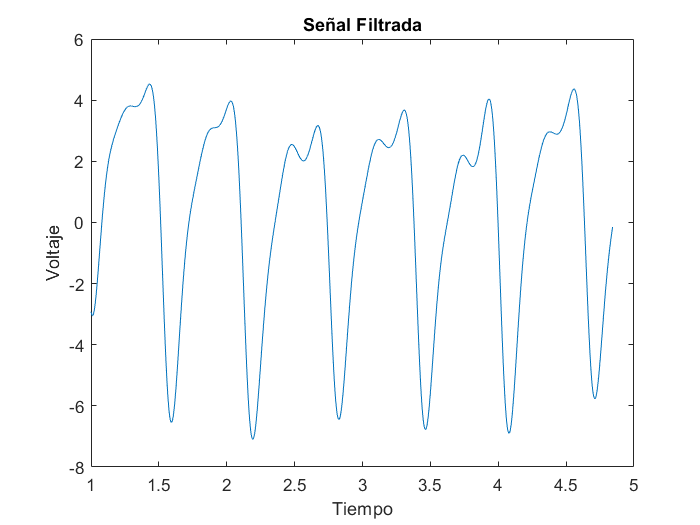


% Diseñar el filtro paso alto
fc = 0.5; % Frecuencia de corte del filtro (ajusta según tus necesidades)
fs = 1 / mean(diff(base_tiempos)); % Frecuencia de muestreo
[b, a] = butter(1, fc/(fs/2), 'high'); % Diseño del filtro

% Aplicamos el filtro
voltaje = filtfilt(b, a,  voltaje_inicial);

% Representamos los datos guardados
plot(base_tiempos, voltaje);
xlabel('Tiempo');
ylabel('Voltaje');
title('Señal Filtrada');

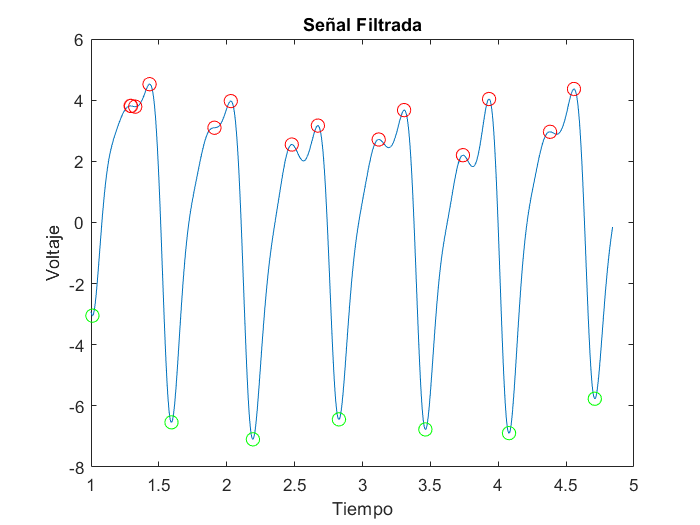


% Encontramos los picos
[maximos, pos_max] = findpeaks(voltaje);

% Calculamos los mínimos
[minimos, pos_min] = findpeaks(-voltaje);

% Eliminamos los datos correspondientes a valores negativos
indicesPositivos = minimos > 0;
minimos = minimos(indicesPositivos);
pos_min = pos_min(indicesPositivos);

% Representamos los valores máximos guardados
figure;
plot(base_tiempos, voltaje);
hold on;
plot(base_tiempos(pos_max), maximos, 'ro', 'MarkerSize', 8);
plot(base_tiempos(pos_min), -minimos, 'go', 'MarkerSize', 8);
xlabel('Tiempo');
ylabel('Voltaje');
title('Señal Filtrada');
hold off;


% Calculamos la diferencia entre posiciones
intervalos = diff(pos_min);

% Asignamos los periodos a cada mínimo
inicio_periodo = 1;
for i = 1:length(intervalos)
    fin_periodo = inicio_periodo + intervalos(i) - 1;
    periodo(inicio_periodo:fin_periodo) = i;
    inicio_periodo = fin_periodo + 1;
end

% Declaramaos los arrrays sistólicos y diastólicos
%side = length(maximos)/2;
systolic = zeros(length(intervalos), 1);
diastolic = zeros(length(intervalos), 1);

% Índice para almacenar los puntos en los arrays 'systolic' y 'diastolic'
indice = 1;

% Almacenamos los puntos de la sístole y diástole
for i = 1:length(intervalos)
    ini_per = pos_min(i);
    fin_per = pos_min(i+1);
    
    % Encontramos los máximos dentro del periodo actual
    periodo_maximos = maximos(pos_max >= ini_per & pos_max <= fin_per);
    
    % Almacenar los puntos 'systolic' y 'diastolic' en los arrays correspondientes
    if length(periodo_maximos) == 1 % Solo hay un máximo en el periodo, es 'systolic'
        systolic(indice) = periodo_maximos;
        diastolic(indice) = NaN;  % Not a number
        indice = indice + 1;
    else % Hay dos máximos en el periodo, el primero es 'systolic' y el segundo es 'diastolic'
        [systolic_max, max_index] = max(periodo_maximos);
        systolic(indice) = systolic_max;
        % Eliminamos el máximo ya almacenado para encontrar el 'diastolic'
        periodo_maximos(max_index) = [];
        diastolic(indice) = max(periodo_maximos);
        indice = indice + 1;
    end   
end

% Ajustar el tamaño de los arrays 'systolic' y 'diastolic' según el número de puntos almacenados
systolic = systolic(1:indice-1);
diastolic = diastolic(1:indice-1);

%Mostrar los puntos "systolic" y "diastolic"
disp('Los puntos "sistólicos" son:');

Los puntos "sistólicos" son:


disp(systolic);

    4.5225
    3.9690
    3.1674
    3.6737
    4.0374
    4.3658



disp('Los puntos "diastólicos" son:');

Los puntos "diastólicos" son:


disp(diastolic);

    3.8111
    3.0976
    2.5479
    2.7126
    2.2000
    2.9644




% Calculamos la media de los puntos sistólicos
media_systolic = mean(systolic)

media_systolic = 3.9560


% Calculamos la media de los puntos diastólicos 
media_diastolic = mean(diastolic(~isnan(diastolic)))

media_diastolic = 2.8889


% Calculamos la media de los puntos mínimos
media_minimos = mean(minimos)

media_minimos = 6.0790


% Calculamos la madida entre el punto medio systolic y el punto medio mínimo
media_referencia = media_systolic - media_minimos

media_referencia = -2.1231


% La refrencia de la sístole y diástole
ref_systolic = 120;
ref_diastolic = 80;

% Utilizamos el método de conversión basado en la amplitud de señal
factor_systolic = ref_systolic/media_systolic;
factor_diastolic = ref_diastolic/media_diastolic;

% Multiplicamos los puntos 'systolic' por 'factor_systolic'
systolic_scaled = systolic * factor_systolic

systolic_scaled =   137.1839
  120.3969
   96.0801
  111.4372
  122.4694
  132.4325



% Multiplicamos los puntos en 'diastolic' por 'factor_diastolic'
diastolic_scaled = diastolic * factor_diastolic

diastolic_scaled =   105.5363
   85.7773
   70.5567
   75.1167
   60.9224
   82.0906



% Definimos los valores de alerta
umbral_systolic = 129;
umbral_diastolic = 80;

% Verificamos y mostramos las alertas para cada periodo
for i = 1:length(systolic)  
    % Verificamos si hay alguna alerta de nivel 1 o nivel 2
    alerta_nivel1 = (systolic_scaled(i) > umbral_systolic) || (diastolic_scaled(i) > umbral_diastolic);
    alerta_nivel2 = (systolic_scaled(i) > umbral_systolic) && (diastolic_scaled(i) > umbral_diastolic);
    % Imprimimos el resultado para el periodo actual
    if alerta_nivel2
        disp(['¡Alerta de nivel 2 en el periodo ', num2str(i), '!']);
    elseif alerta_nivel1
        disp(['¡Alerta de nivel 1 en el periodo ', num2str(i), '!']);
    else
        disp(['OK en el periodo ', num2str(i)]);
    end
end

¡Alerta de nivel 2 en el periodo 1!


¡Alerta de nivel 1 en el periodo 2!


OK en el periodo 3
OK en el periodo 4
OK en el periodo 5


¡Alerta de nivel 2 en el periodo 6!



% Calculamos los tiempos entre periodos
tiempo_entre_periodos = diff(base_tiempos(pos_min));

% Mostramos los tiempos entre periodos
disp('Los tiempos entre periodos son:');

Los tiempos entre periodos son:


disp(tiempo_entre_periodos);

    0.5824
    0.6000
    0.6336
    0.6368
    0.6160
    0.6320




% Ahora calculamos la frecuencia
frecuencia_base = 1./tiempo_entre_periodos

frecuencia_base =     1.7170
    1.6667
    1.5783
    1.5704
    1.6234
    1.5823


frecuencia_media = mean(frecuencia_base);

% Mostramos los tiempos entre periodos
disp('La frecuencia media es:');

La frecuencia media es:


disp(frecuencia_media);

    1.6230




% Definimo umbrales de frecuencia cardíaca
freq_baja = 1;
freq_alta = 3.33;

% Comprobamos si la frecuencia media está en un rango adecuado
if frecuencia_media < freq_baja
    disp('Ritmo cardíaco medio MUY BAJO'); 
elseif frecuencia_media > freq_alta
    disp('Ritmo cardíaco medio MUY ALTO'); 
else
    disp('Ritmo cardíaco medio CORRECTO');
end

Ritmo cardíaco medio CORRECTO



% Hacemos lo mismo periodo a periodo
for i = 1:length(frecuencia_base)
    % Definimos variables para lso ritmos
    ritmo_bajo = frecuencia_base(i) < freq_baja;
    ritmo_alto = frecuencia_base(i) > freq_alta; 
    if ritmo_bajo
        disp(['¡Irregularidad, ritmo BAJO en el periodo ', num2str(i), '!']);
    elseif ritmo_alto
        disp(['¡Irregularidad, ritmo ALTO en el periodo ', num2str(i), '!']);
    else
        disp(['Ritmo OK en el periodo ', num2str(i)]);
    end
end

Ritmo OK en el periodo 1
Ritmo OK en el periodo 2
Ritmo OK en el periodo 3
Ritmo OK en el periodo 4
Ritmo OK en el periodo 5
Ritmo OK en el periodo 6


**DERIVADA**

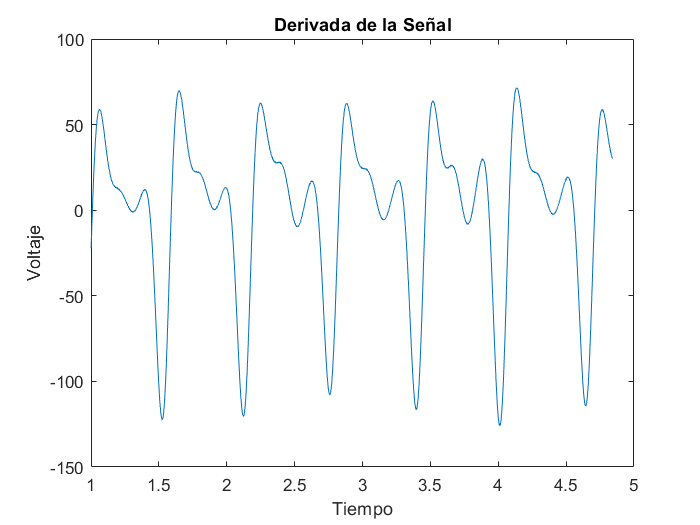

% Calculamos la derivada de la señal
derivada_voltaje = diff(voltaje) ./ diff(base_tiempos);
plot(base_tiempos(1:end-1), derivada_voltaje);
xlabel('Tiempo');
ylabel('Voltaje');
title('Derivada de la Señal');

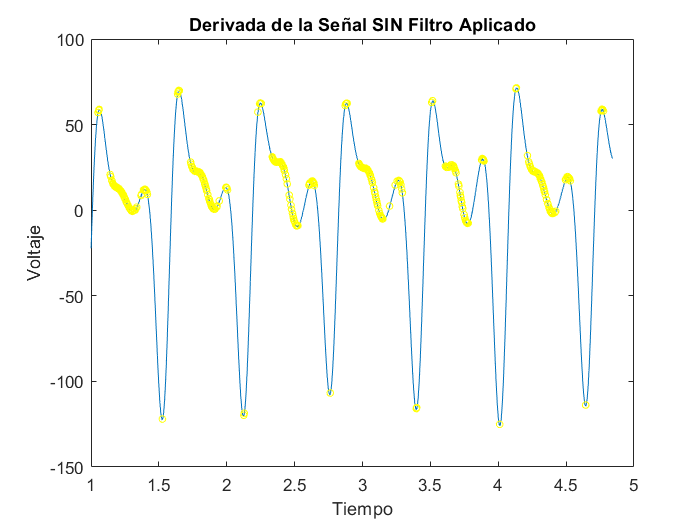


%Encontramos todos los picos
[picos_general_prev, pos_general_prev] = findpeaks(derivada_voltaje);

%Los representamos
figure;
plot(base_tiempos(1:end-1), derivada_voltaje);
hold on;
plot(base_tiempos(pos_general_prev), picos_general_prev, 'yo', 'MarkerSize', 4);
xlabel('Tiempo');
ylabel('Voltaje');
title('Derivada de la Señal SIN Filtro Aplicado');
hold off;


%Filtramos la derivada
fs = 500;
f_corte = 4;
orden_filtro = 4;
filtro = designfilt('lowpassiir', 'FilterOrder', orden_filtro, 'PassbandFrequency', f_corte, 'SampleRate', fs);
derivada_voltaje_filt = filtfilt(filtro, derivada_voltaje);

%Límite de corte
lim = 31;

%Encontramos todos los picos de la señal filtrada
[picos_general, pos_general] = findpeaks(derivada_voltaje_filt);

%Separamos los valores menores del límite impuesto
indice_ini = picos_general < lim;
maximos_d = picos_general(indice_ini);
pos_max_d = pos_general (indice_ini);

%Encontramos picos mayores que 50
[maximos_dx, pos_max_dx] = findpeaks(derivada_voltaje_filt, 'MinPeakHeight',50);
maximos_dx

maximos_dx =    55.0923
   60.6714
   60.9266
   58.8616
   56.4186
   66.9231



%Calculamos la media de ambos valores
media_d = mean(maximos_d)

media_d = 22.7457

media_dx = mean(maximos_dx)

media_dx = 59.8156


% Calculamos la diferencia porcentual entre los picos y la media
diferencia_porcentual_d = abs(maximos_d - media_d) ./ media_d * 100;
diferencia_porcentual_dx = abs(maximos_dx - media_dx) ./ media_dx * 100;

% Definimos el umbral del 10%
umbral_d = 55;
umbral_dx = 11;

% Verificamos si la diferencia porcentual supera el umbral y activamos la alarma
if any(diferencia_porcentual_d > umbral_d)
    [~, indice_max_d] = max(diferencia_porcentual_d);
    disp(['¡Debe volver a revisarse la presión arterial!', newline, 'Diferencia porcentual de maximos_d mayor al 50%. Valor máximo: ', num2str(maximos_d(indice_max_d))]);
else
    disp('Revisión 1 completa. Presión arterial adecuada. Prueba 1');
end

¡Debe volver a revisarse la presión arterial!
Diferencia porcentual de maximos_d mayor al 50%. Valor máximo: 10.0605



if any(diferencia_porcentual_dx > umbral_dx)
    [~, indice_max_dx] = max(diferencia_porcentual_dx);
    disp(['¡Debe volver a revisarse la presión arterial!', newline, 'Diferencia porcentual de maximos_dx mayor al 10%. Valor máximo: ', num2str(maximos_dx(indice_max_dx))]);
else
    disp('Revisión 2 completa. Presión arterial adecuada. Prueba 2');
end

¡Debe volver a revisarse la presión arterial!
Diferencia porcentual de maximos_dx mayor al 10%. Valor máximo: 66.9231


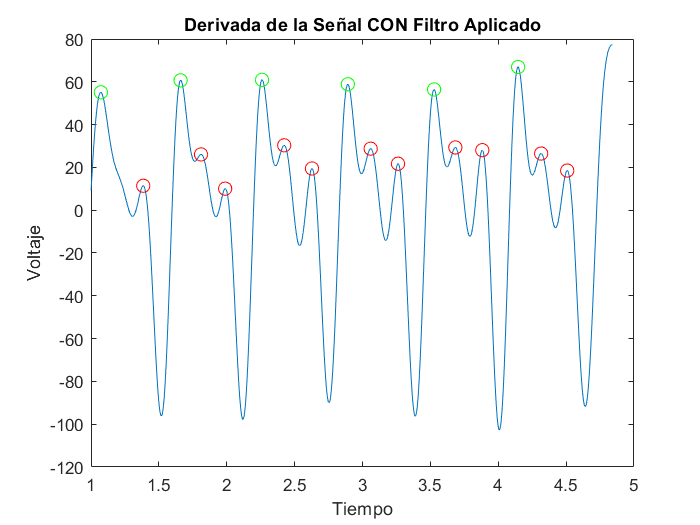


figure;
plot(base_tiempos(1:end-1), derivada_voltaje_filt);
hold on;
plot(base_tiempos(pos_max_d), maximos_d, 'ro', 'MarkerSize', 8);
plot(base_tiempos(pos_max_dx), maximos_dx, 'go', 'MarkerSize', 8);
xlabel('Tiempo');
ylabel('Voltaje');
title('Derivada de la Señal CON Filtro Aplicado');
hold off;

**NUEVA SEÑAL**

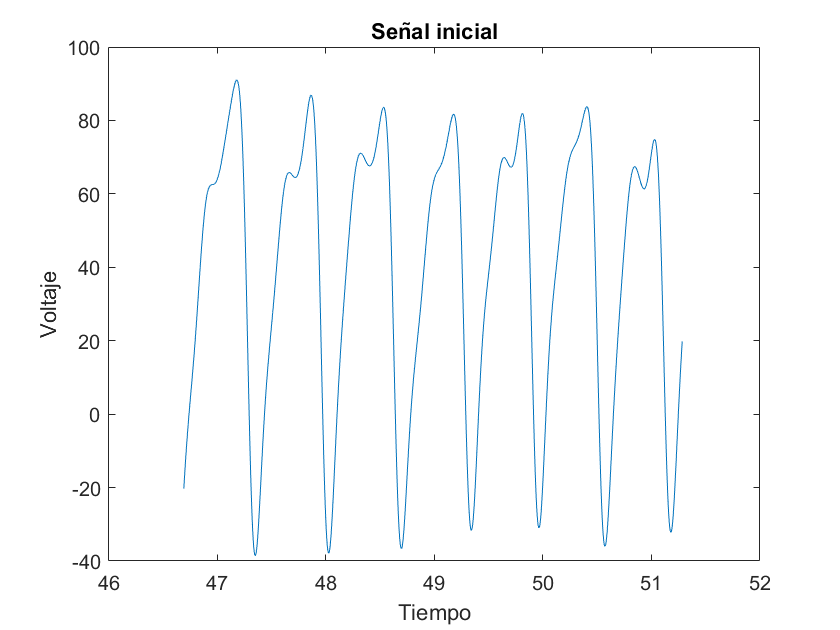

ruta_pa_new = 'D:\Master\Segundo Cuatrimestre\Trabajo Fin de Master\TFM presion arterial\Excel\Para_matlab\Nueva_signal.csv';

% Se lee el csv
datos_pa_new = csvread(ruta_pa_new);

%Establecemos un offset
offset = 20;

% Extraemos columnas
base_tiempos_new = datos_pa_new(:, 1);
voltaje_new = datos_pa_new(:, 2) + offset;

% Representamos los datos guardados
plot(base_tiempos_new, voltaje_new);
xlabel('Tiempo');
ylabel('Voltaje');
title('Señal inicial');

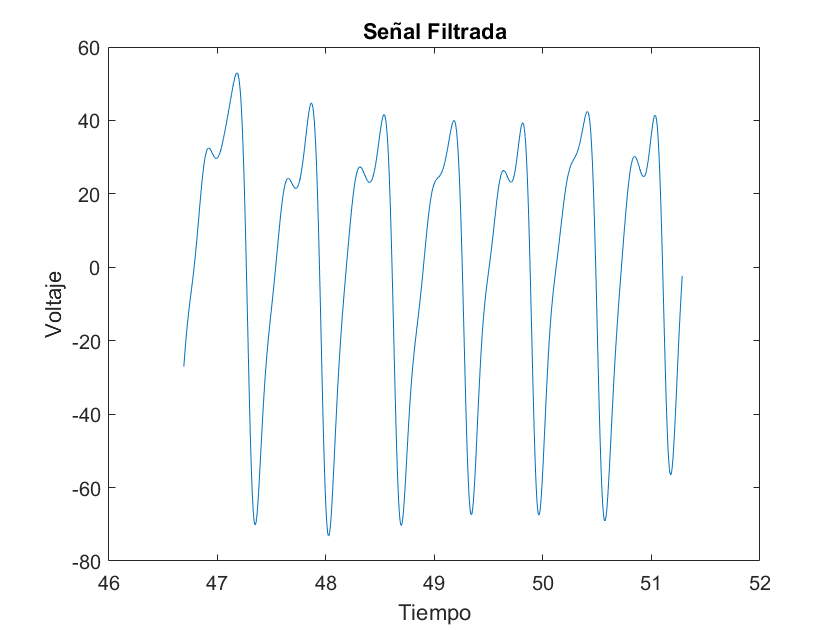


% Diseñar el filtro paso alto
fc = 0.5; % Frecuencia de corte del filtro (ajusta según tus necesidades)
fs = 1 / mean(diff(base_tiempos_new)); % Frecuencia de muestreo
[b, a] = butter(1, fc/(fs/2), 'high'); % Diseño del filtro

% Aplicar el filtro
voltaje_filt = filtfilt(b, a, voltaje_new);

% Representamos los datos guardados
plot(base_tiempos_new, voltaje_filt);
xlabel('Tiempo');
ylabel('Voltaje');
title('Señal Filtrada');

**DERIVADA Y SEGUNDA DERIVADA NUEVA SEÑAL**

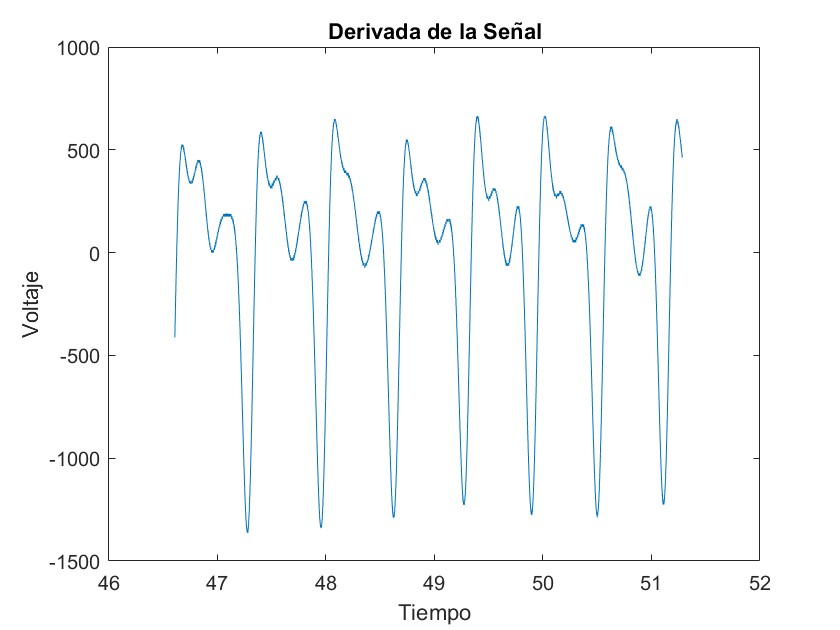


% Calculamos la derivada de la señal
derivada_voltaje = diff(voltaje) ./ diff(base_tiempos);
plot(base_tiempos(1:end-1), derivada_voltaje);
xlabel('Tiempo');
ylabel('Voltaje');
title('Derivada de la Señal');

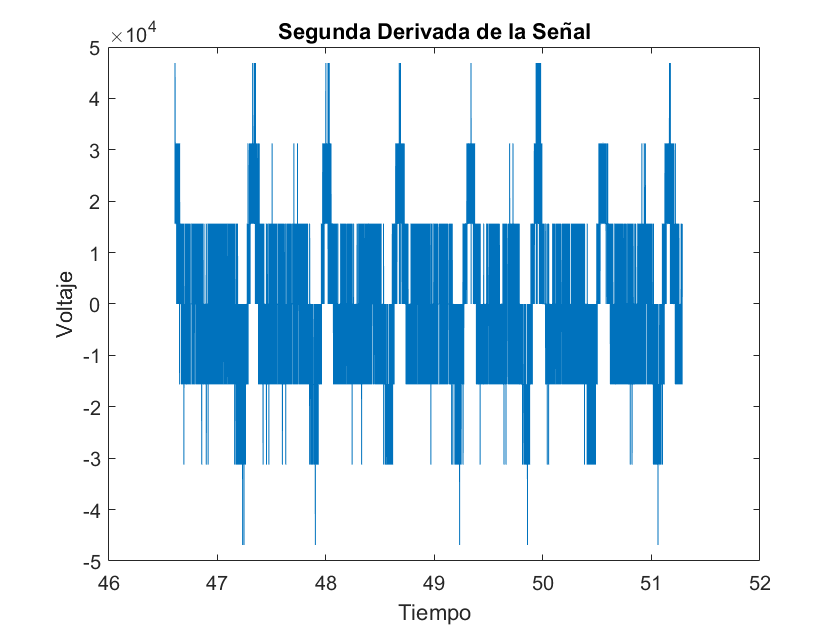


% Segunda derivada
segunda_derivada_voltaje = diff(diff(voltaje)) ./ (diff(base_tiempos(1:end-1)) .* diff(base_tiempos(2:end)));
plot(base_tiempos(2:end-1), segunda_derivada_voltaje);
xlabel('Tiempo');
ylabel('Voltaje');
title('Segunda Derivada de la Señal');

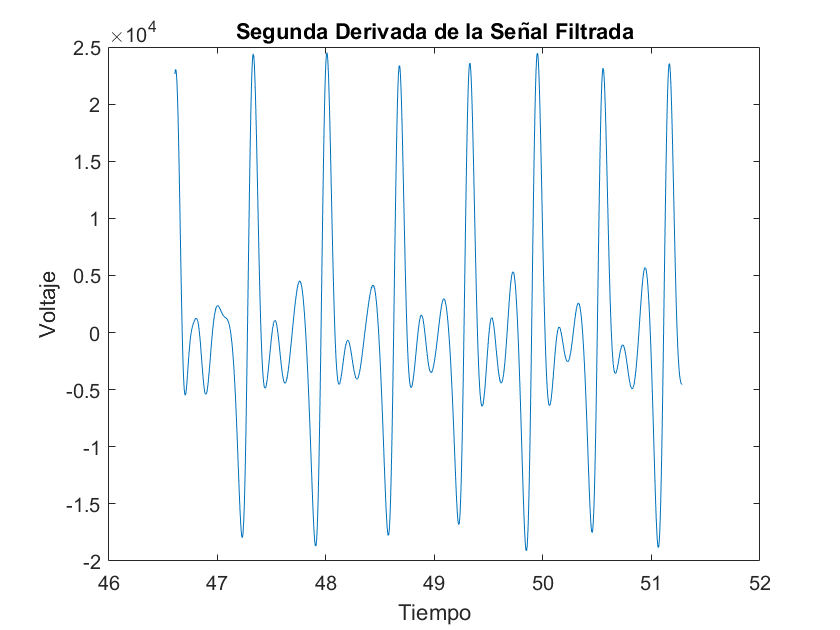


% Filtro segunda derivada
fs = 500;
f_corte = 4;
orden_filtro = 4;
filtro = designfilt('lowpassiir', 'FilterOrder', orden_filtro, 'PassbandFrequency', f_corte, 'SampleRate', fs);
segderiv_filtrada = filtfilt(filtro, segunda_derivada_voltaje);

plot(base_tiempos(2:end-1), segderiv_filtrada);
xlabel('Tiempo');
ylabel('Voltaje');
title('Segunda Derivada de la Señal Filtrada');